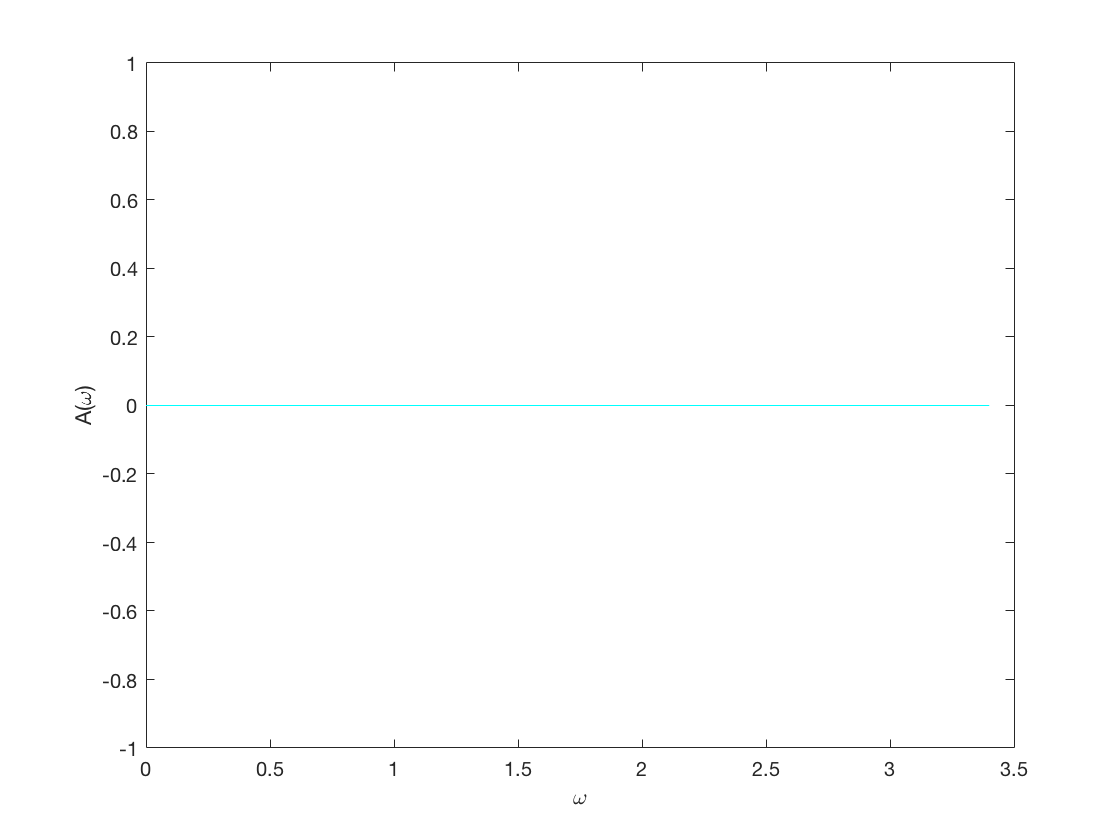

% a) initial conditions: theta0 = 0, theta0dot= 0
%compute A(w) for omega = 0,1,2,2.2,2.4,2.6,2.8,3,3.2,3.4
% with omega0 =3 and Gamma =0.5
%plot A(w) VS omega 
% max A the resonance angual freq omega is max

Gamma=0.5; 
freq=[0, 1.0, 2.0, 2.2, 2.4, 2.6, 2.8, 3.0, 3.2, 3.4];
Amplitude=zeros(length(freq),1);

for i=1:length(freq)
   [T,sol]=Forced_pendulummodified(1.09, 0,0,0,Gamma,freq(i)); 
   l=length(sol(:,1)) ;
   l=double(l/2);
   Max=sol(end-l:end,2);
   Amplitude(i) = max(Max);
   
end    

figure;
plot(freq,Amplitude,'c');

xlabel('\omega');
ylabel('A(\omega)');

[Amplitudemax,ind]=max(Amplitude); 
freqmax=freq(ind);
ind1=0;
ind2=0;
for i=1:length(freq)
    if Amplitude(i) <= (1 ./ sqrt(2)) * Amplitudemax && freq(i) < freqmax
        ind1=i;
    end
    
    if Amplitude(i) <= (1 ./ sqrt(2)) * Amplitudemax && freq(i) > freqmax
        ind2=i;
    end
end    

deltafreq=freq(ind2)-freq(ind1);

Subscript indices must either be real positive integers or logicals.



fprintf(' max Amplitude = %f ',Amplitudemax);
fprintf('max omega = %f',freqmax);
fprintf('delta omega = %f',deltafreq);
    

